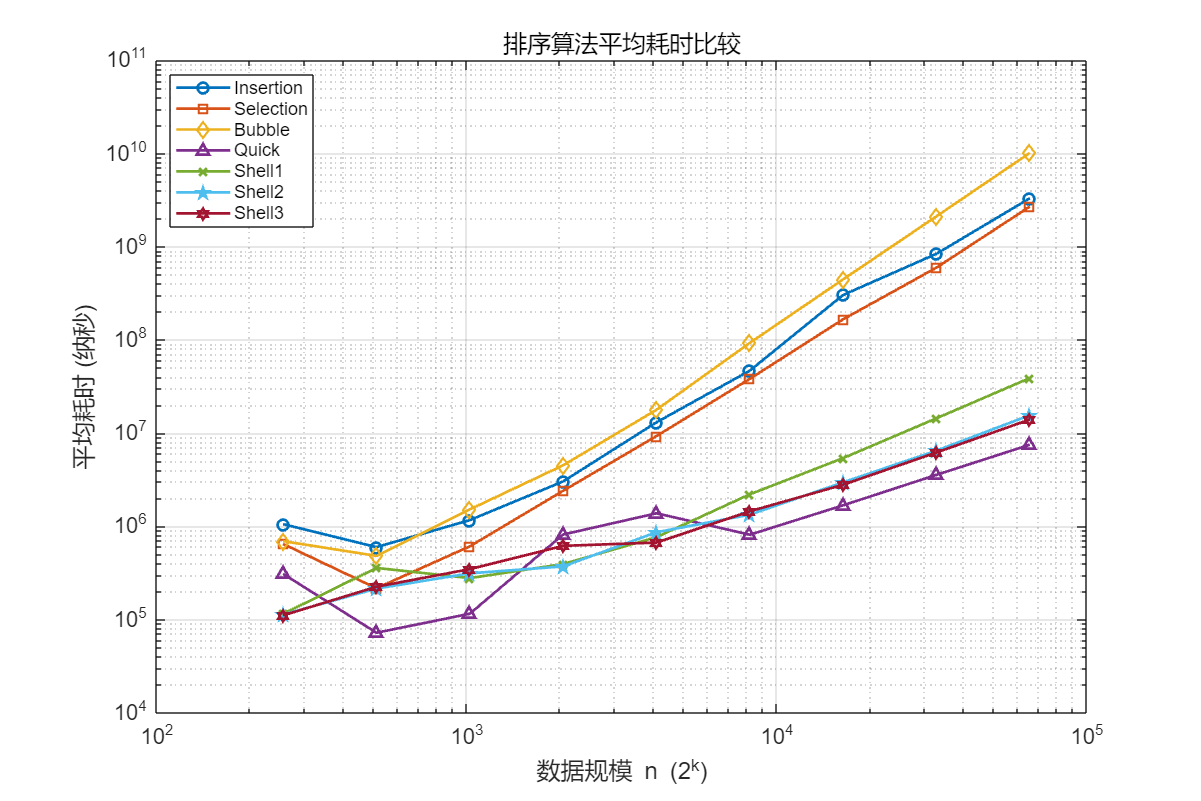

% 数据规模（2^8 ~ 2^16）
n = [256 512 1024 2048 4096 8192 16384 32768 65536];

% 各排序算法平均耗时（纳秒）
Insertion = [1055120 598100 1166420 3031620 13065700 46855120 303996900 840341380 3316836640];
Selection = [646480 216680 609920 2405920 9296760 38262260 166651400 597083060 2701324600];
Bubble = [693300 481600 1519060 4516740 17821120 92957220 446861160 2123296680 10168984160];
Quick = [309260 72100 115340 816640 1379500 813040 1681160 3568260 7512020];
Shell1 = [115060 357780 278120 393760 765840 2205680 5400060 14440480 39036000];
Shell2 = [112920 214720 312880 371380 864000 1333920 2966840 6498000 15565860];
Shell3 = [110720 224660 347160 617220 669540 1449180 2796480 6203560 13992740];

% 绘制性能曲线（双对数坐标）
figure('Position', [100, 100, 1200, 800]);
loglog(n, Insertion, '-o', 'LineWidth', 1.5); hold on;
loglog(n, Selection, '-s', 'LineWidth', 1.5);
loglog(n, Bubble, '-d', 'LineWidth', 1.5);
loglog(n, Quick, '-^', 'LineWidth', 1.5);
loglog(n, Shell1, '-x', 'LineWidth', 1.5);
loglog(n, Shell2, '-p', 'LineWidth', 1.5);
loglog(n, Shell3, '-h', 'LineWidth', 1.5);

% 样式与标签
grid on;
xlabel('数据规模 n (2^k)', 'FontSize', 12);
ylabel('平均耗时 (纳秒)', 'FontSize', 12);
title('排序算法平均耗时比较', 'FontSize', 14);
legend({'Insertion','Selection','Bubble','Quick','Shell1','Shell2','Shell3'}, ...
    'Location', 'northwest', 'FontSize', 10);
set(gca, 'FontSize', 12);